# Abstract clustering

## Selection criteria for papers focusing on Machine Learning used for Gas Sensning

addpath("PubMedAccess/");
api_key = [];
email = "a.a.lensky@gmail.com";

% Different selection criteria
% ------------------------------------------------------
gas_sensor_text  =  ['"concentration prediction"[ab/ti] OR "gas recognition"[ab/ti] OR' ...
                     ' "gas sensing"[ab/ti] OR "gas sensor"[ab/ti] OR "gas sensors"[ab/ti] OR' ...
                     ' "artificial nose"[ab/ti] OR "electronic nose"[ab/ti] OR' ...
                     ' "e-nose"[ab/ti] OR olfactory[ab/ti]'];

ml_text          =  ['intelligence[ab/ti] OR "machine learning"[ab/ti] OR "deep learning"[ab/ti] OR' ...
                     ' "ensemble learning"[ab/ti] OR "incremental Learning"[ab/ti] OR ' ...
                     ' "autoencoder"[ab/ti] OR "active learning"[ab/ti] OR ' ...
                     ' "neural network"[ab/ti] OR "neural networks"[ab/ti] OR LSTM[ab/ti] OR' ...
                     ' "anomaly detection"[ab/ti]  OR "spiking"[ab/ti]'];

metaloxide_text  =  'oxides OR oxide OR MOS OR MOX';

voc_text         =   'volatile organic compound[ab/ti] or VOC[ab/ti]';

not_text         =  'NOT MEMS[ab/ti] NOT NEMS[ab/ti] NOT FET[ab/ti] NOT "metal oxide graphene"[ab/ti] NOT MOG[ab/ti]';
% ------------------------------------------------------

% Combined the above criteria into a final query
query = ['(', gas_sensor_text, ') AND (', ml_text, ') AND (' metaloxide_text, ')',' ',  not_text];

% Selection date
startYear = 2015;
endYear   = 2024;

## Request PMC articles

% Request PMC paper IDs
database = "pmc";
email = "something@mail.au";
idPMC = requestIDs(query, email, startYear, endYear, database);
% Request articles with these IDs
disp("The number of identified papers: " + height(idPMC));

The number of identified papers: 287


articlesPMC = requestArticles(idPMC, email, database);

metadata = struct with fields:
    PMCID: 4510100
      DOI: "10.1016/j.dib.2015.02.016"
     PMID: 26217733
    Title: "Data set from gas sensor array under flow modulation^"


[9345448]:9345448:Is it possible to rapidly and noninvasively identify different plants from (Asteraceae) using electronic nose with multiple mathematical algorithms?
[4455291]:4455291:Stable Odor Recognition by a neuro-adaptive Electronic Nose
[4431300]:4431300:A Wireless and Portable Electronic Nose to Differentiate Musts of Different Ripeness Degree and Grape Varieties
[4510100]:4510100:Data set from gas sensor array under flow modulation^
[4601313]:4601313:E-nose based rapid prediction of early mouldy grain using probabilistic neural networks
[5087530]:5087530:Chocolate Classification by an Electronic Nose with Pressure Controlled Generated Stimulation
[5281663]:5281663:Feasibility of electronic nose technology for discriminating between head and neck, bladder, and colon carcinomas
[10717437]:10717437:Functiogenesis of the embryonic central nervous system revealed by optical recording with a voltage-sensitive dye
[5001212]:5001212:25th Annual Computational Neuroscience Meeting: CNS


disp(articlesPMC);

      PMCID                       DOI                        PMID                                                                                                                           Title                                                                                                                            Authors          PubDate                                                                        Journal                                                                                                                                                                                                                                                                                                                                                                                                                                                                             

## Request PubMed articles

% Request PMC paper IDs
database = "pubmed";
idPM = requestIDs(query, email, startYear, endYear, "pubmed");
disp("The number of identified papers: " + height(idPM));

The number of identified papers: 284


% Request articles with these IDs
articlesPM = requestArticles(idPM, email, database);

disp(articlesPM);

       PMID                                                                                                                   Title                                                                                                                    Authors         PubDate                                                                                        Journal                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                      

## Merge PubMed and PubMedCentral and remove duplicates

% Find IDs that are in PMC but not in PubMed
articlesPMCdiff = setdiff(articlesPMC.PMID, articlesPM.PMID);
articlesPMCdiff = articlesPMCdiff(articlesPMCdiff ~=0);

% Merge PubMed and PMC in articles table
articles = articlesPM;
columnNames = intersect(articlesPMC.Properties.VariableNames, articlesPM.Properties.VariableNames);

for k = 1:length(articlesPMCdiff)
    articles = [articles; articlesPMC(articlesPMCdiff(k) == articlesPMC.PMID, columnNames)];
end

[~ , uniquePMIDs] = unique(articles.PMID);
articles = articles(uniquePMIDs, :);
disp(articles)

       PMID                                                                                                                           Title                                                                                                                            Authors          PubDate                                                                                        Journal                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                     

## Visualise number of paper by year

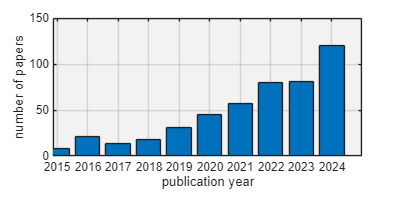

years = articles.PubDate;
figure(color="white", Position=[0 0 400 200]), 
nexttile
set(gca,'Color', [0.95, 0.95, 0.95]), 
box on, hold on, grid on;
uniqueYears = unique(years);
[hc, y] = histcounts(years, BinMethod="year");
h = bar(y, [hc, 0], 'BarWidth',0.8); %  FaceColor="#80B3FF"
xlabel("publication year");
ylabel("number of papers");
xlim([(min(years)), (max(years))])

## Compute the embedding of the abstracts using MiniLM

abstracts = articles.Abstract;
try
    barHandle = waitbar(0);
    emb = documentEmbedding(Model="all-MiniLM-L12-v2"); % Why MiniLM https://arxiv.org/pdf/2401.01943
    
    clear sumMiniLMEmb;
    barHandle = waitbar(0);
    for k = 1:length(abstracts)
        sumMiniLMEmb(k, :) = embed(emb, abstracts(k));
        waitbar((k-1)/length(abstracts), barHandle, "Processing");
    end
    close(barHandle);
catch err
    close(barHandle);
    error("This part requires documentEmbedding and all-MiniLM-L12-v2 be installed");
end

## Compute the embedding of the abstracts using LLMs

model = 'qwen2.5:0.5b'; %'llama3.2:1b'; qwq:32b
llmOptions = struct('temperature', 0, 'seed', 42);
computeEmbedding = @(text) webwrite('http://localhost:11434/api/embeddings', struct('model', model, 'prompt', text, 'raw', true, 'options', llmOptions), weboptions(MediaType='application/json', Timeout=120)).embedding;
computeResponse  = @(text) string(webwrite('http://localhost:11434/api/generate', struct('model', model, 'prompt', text, 'raw', true, 'stream', false, 'options', llmOptions), weboptions(MediaType='application/json', Timeout=120)).response).strip;
modelRest        = @() webwrite('http://localhost:11434/api/generate ', struct('model', model, 'keep_alive', 0));


try
    barHandle = waitbar(0);    
    response = computeEmbedding("test");
    sumLLLMEmb = zeros(length(abstracts), size(response,1));
    clear sumLLLMEmb;
    
    for k = 1:length(abstracts)
        embedding = computeEmbedding(abstracts(k));
        sumLLLMEmb(k, :) = embedding;
        waitbar((k-1)/length(abstracts), barHandle, "Processing");
    end
    close(barHandle)
catch err
    close(barHandle)
    error("Ollama and " + model + " should be installed")
end

## Cluster and visualise the MiniLM embeddings

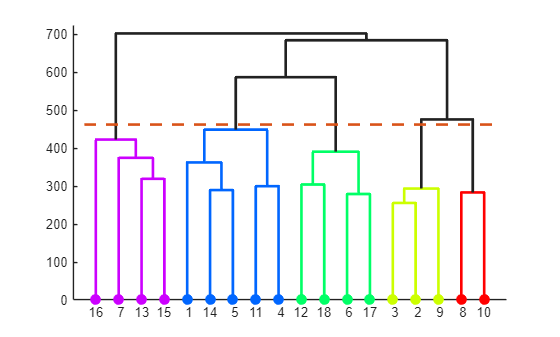

numClusters = 5;
distance1 = "sqeuclidean";
distance2 = "euclidean";
clusteringType = "linkage" % "kmeans"

if (clusteringType == "kmeans")
    [articleClusterID, C] = kmeans(sumLLAMAEmb, numClusters, Distance=distance1, Replicates=3, start="cluster");
elseif (clusteringType == "linkage")
        Z = linkage(sumLLLMEmb,'ward', distance2);
    %Z = linkage(sumMiniLMEmb,'average', distance2);
    articleClusterID = cluster(Z,'Maxclust', numClusters);
    %articleClusterID = cluster(Z,Cutoff=1.2,Criterion="inconsistent");
end

figure
cutoff = median([Z(end-numClusters,3) Z(end,3)]);
[dg, T, outperm] = dendrogram(Z, 18, ColorThreshold=cutoff, ClusterIndices=articleClusterID, ShowMarkers=true,ShowCut=true);
set(dg, LineWidth=2);

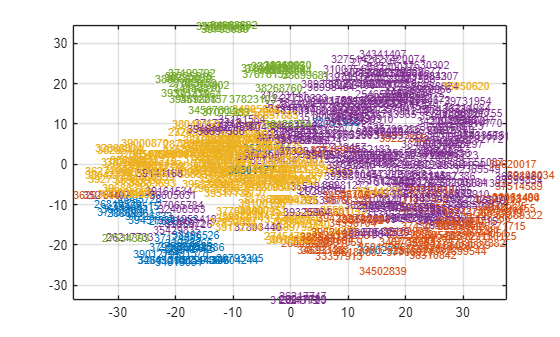

axDendogram = dg.Parent;
%exportgraphics(gcf,'./Figures/dendogram2.pdf');

colors = lines(numClusters);

Y = tsne(sumLLLMEmb,'Algorithm','exact','Standardize',true,'Perplexity',30, Distance=distance2);
figure, hold on; grid on; box on;
for k = 1:size(sumLLLMEmb, 1)
    text(Y(k, 1), Y(k, 2), string(articles(k,:).PMID), FontSize=8, Color=colors(articleClusterID(k), :));
end

xlim([min(Y(:, 1)), max(Y(:, 1))]);
ylim([min(Y(:, 2)), max(Y(:, 2))]);

## Preprocess articles for computing  Word-level LDA

numMostFreqWords    = 10; % Used to remove most frequently used words
numOfInfreqWords    = 25; % Used to remove least frequently used words

abstracts_ = preprocessText(abstracts);
bagAll     = bagOfWords(abstracts_);

bagAll = removeInfrequentWords(bagAll, numOfInfreqWords);
[bagAll,docsRemoved] = removeEmptyDocuments(bagAll); 

tbl = topkwords(bagAll ,numMostFreqWords);
% 
% % Remove the top most frequent words from the bag-of-words model
% bagAll = removeWords(bagAll,tbl.Word);
clear bagOfWords_;
for clusterID = 1:numClusters
    bagOfWords_(clusterID)              = bagOfWords(abstracts_(articleClusterID == clusterID));
    bagOfWords_(clusterID)              = removeInfrequentWords(bagOfWords_(clusterID), numOfInfreqWords);
    bagOfWords_(clusterID)              = removeEmptyDocuments(bagOfWords_(clusterID)); 
    bagOfWords_(clusterID)              = removeWords(bagOfWords_(clusterID), tbl.Word);
end

## Visualise bags of words for each cluster

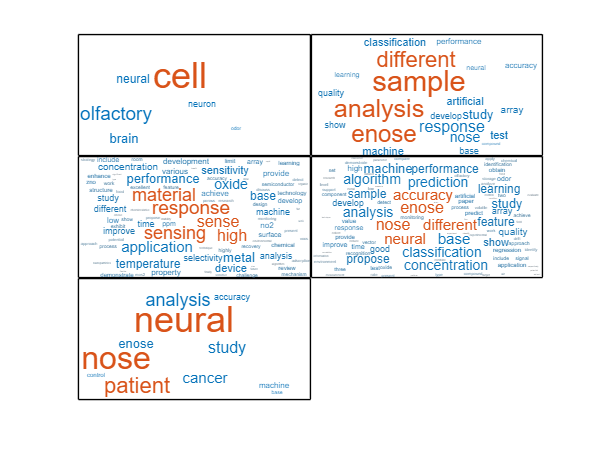

numColumns = 2;
figure(Position=[0 0 600 450], Color="white"), hold on;
tiledlayout(ceil(numClusters/numColumns), numColumns, "TileSpacing", "tight");
for clusterID = 1:numClusters
        nexttile
        wordcloud(bagOfWords_(clusterID), Color=[0 0.4470 0.7410], HighlightColor=[0.8500 0.3250 0.0980], Shape='rectangle');
        box on;
end

## Compute Word-level LDA for each cluster and plot latent topics

numTopics = 3;
plotTopics = 1:numTopics; % choose first numTopics topics to plot
clear ldaModels;
for clusterID = 1:numClusters
    ldaModels(clusterID) = fitlda(bagOfWords_(clusterID),numTopics, 'Solver','cvb0','IterationLimit',500); %cvb0
end

| Iteration  |  Time per  |  Relative  |  Training  |     Topic     |     Topic     |
|            | iteration  | change in  | perplexity | concentration | concentration |
|            | (seconds)  |   log(L)   |            |               |   iterations  |
|          0 |       0.01 |            |  6.803e+00 |         0.750 |             0 |
|          1 |       0.00 | 1.1253e-01 |  5.603e+00 |         0.750 |             0 |
|          2 |       0.00 | 1.0301e-02 |  5.506e+00 |         0.750 |             0 |
|          3 |       0.00 | 1.0806e-02 |  5.406e+00 |         0.750 |             0 |
|          4 |       0.00 | 1.3705e-02 |  5.284e+00 |         0.750 |             0 |
|          5 |       0.00 | 1.6249e-02 |  5.146e+00 |         0.750 |             0 |
|          6 |       0.00 | 1.6655e-02 |  5.009e+00 | 

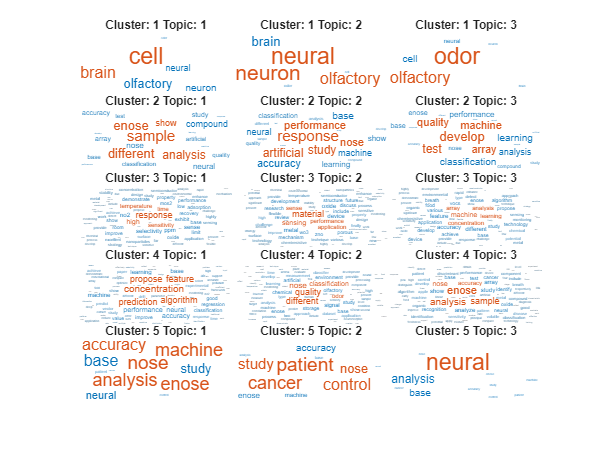



figure(Position=[0 0 600 450], Color="white"), hold on;
tiledlayout(numClusters, numTopics, "TileSpacing", "tight");
for clusterID = 1:numClusters
    for k = 1:numTopics
        nexttile
        wordcloud(ldaModels(clusterID), plotTopics(k), Color=[0 0.4470 0.7410], HighlightColor=[0.8500 0.3250 0.0980], Shape='rectangle');
        [~, topTopics] = max(ldaModels(clusterID).DocumentTopicProbabilities,[],2);
        title("Cluster: " + clusterID + " Topic: " + k)
    end
end

## Preprocess articles for computing  nGram-level LDA

numMostFreqNGrams = 2;
for clusterID = 1:numClusters
    bagNGram(clusterID)   = bagOfNgrams(abstracts_(articleClusterID == clusterID), NgramLengths=[2, 3]);
    tbl                   = topkngrams(bagNGram(clusterID), numMostFreqNGrams);
    bagNGram(clusterID)   = removeNgrams(bagNGram(clusterID), tbl.Ngram, 'IgnoreCase',true);
end

## Create topic models

rng('default') % setting random number seed for reproducibility
numDocuments = height(abstracts_);
cvp = cvpartition(numDocuments, HoldOut=0.2); % setting aside 20% for validation
documentsTrain      = abstracts_(cvp.training);
documentsValidation = abstracts_(cvp.test);

bagNGramTrain = bagOfNgrams(documentsTrain);
[bagNGramTrain, ~] = removeEmptyDocuments(bagNGramTrain); 

tbl = topkngrams(bagNGramTrain ,numMostFreqWords);
bagNGramTrain = removeNgrams(bagNGramTrain, tbl.Ngram);

bagNGramTest = bagOfNgrams(documentsValidation);
[bagNGramTest, ~] = removeEmptyDocuments(bagNGramTest); 

tbl = topkngrams(bagNGramTest, numMostFreqWords);
bagNGramTest = removeNgrams(bagNGramTest, tbl.Ngram);


numObservations = bagNGramTrain.NumDocuments;
solvers = ["cgs" "avb" "cvb0" "savb"]; 
lineSpecs = ["+-" "*-" "x-" "o-"];
figure
for i = 1:numel(solvers)
    i
    solver = solvers(i);
    lineSpec = lineSpecs(i);
    
    if solver == "savb"
        numIterationsPerDataPass = ceil(numObservations/10);
    else
        numIterationsPerDataPass = 1;
    end
    mdl = fitlda(bagNGramTrain, 5, ...
        'Solver',solver, ...
        'InitialTopicConcentration',1, ...
        'FitTopicConcentration',false, ...
        'ValidationData',bagNGramTest, ...
        'ValidationFrequency',numIterationsPerDataPass, ...
        'Verbose',0);
    
    history = mdl.FitInfo.History;
    
    timeElapsed = history.TimeSinceStart;
    validationPerplexity = history.ValidationPerplexity;
    
    % Remove NaNs.
    idx_ = isnan(validationPerplexity);
    timeElapsed(idx_) = [];
    validationPerplexity(idx_) = [];
    
    semilogx(timeElapsed,validationPerplexity,lineSpec)
    hold on 
end

i = 1

i = 2

i = 3

i = 4


xlabel("Time Elapsed (s)")
ylabel("Validation Perplexity")
ylim([0 inf])
legend(solvers)

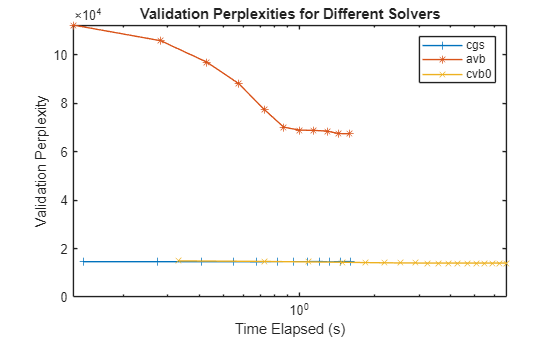

title('Validation Perplexities for Different Solvers')

## Compute nGram-level LDA for each cluster and plot latent topics 

numTopics = 3; % Temp!!! 
plotTopics = 1:numTopics; % choose first numTopics topics to plot
for clusterID = 1:numClusters
    ldaModels(clusterID) = fitlda(bagNGram(clusterID), numTopics, 'Solver','cvb0','IterationLimit',500); %cvb0
end

| Iteration  |  Time per  |  Relative  |  Training  |     Topic     |     Topic     |
|            | iteration  | change in  | perplexity | concentration | concentration |
|            | (seconds)  |   log(L)   |            |               |   iterations  |
|          0 |       0.00 |            |  8.832e+03 |         0.750 |             0 |
|          1 |       0.00 | 3.5919e-02 |  6.445e+03 |         0.750 |             0 |
|          2 |       0.00 | 1.9257e-02 |  5.461e+03 |         0.750 |             0 |
|          3 |       0.00 | 2.4195e-02 |  4.456e+03 |         0.750 |             0 |
|          4 |       0.00 | 2.4269e-02 |  3.652e+03 |         0.750 |             0 |
|          5 |       0.00 | 1.9236e-02 |  3.128e+03 |         0.750 |             0 |
|          6 |       0.00 | 1.1425e-02 |  2.856e+03 | 

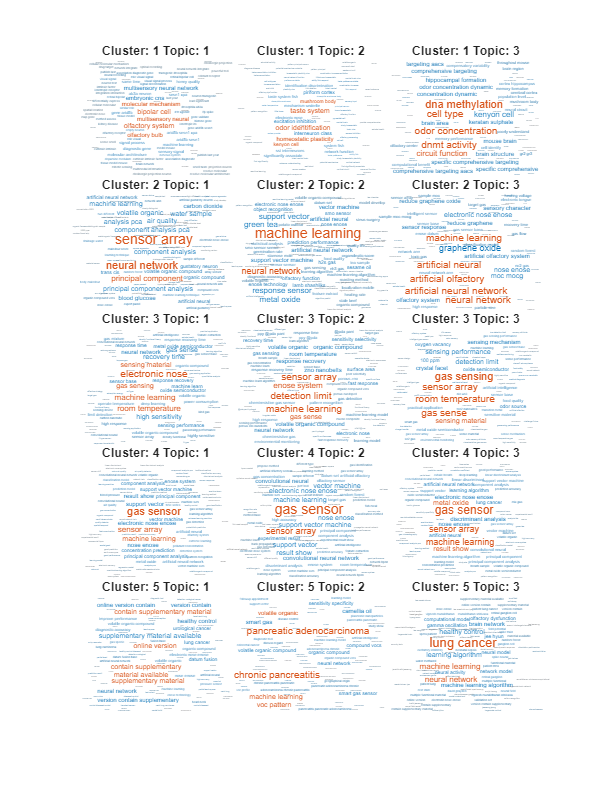


figure(Position=[0 0 600 800], Color="white"), hold on;
tiledlayout(numClusters, numTopics, "TileSpacing", "tight");
for clusterID = 1:numClusters
    for topicID = 1:numTopics
        nexttile
        wordcloud(ldaModels(clusterID), plotTopics(topicID), Color=[0 0.4470 0.7410], HighlightColor=[0.8500 0.3250 0.0980], Shape='rectangle');
        [~, topTopics] = max(ldaModels(clusterID).DocumentTopicProbabilities,[],2);
        title("Cluster: " + clusterID + " Topic: " + topicID)
    end
end

%exportgraphics(gcf,'./Figures/topicsPerCluster.pdf');

## Visualise the space of clustered papers

probPerTopicCombined = [];
topTopicsCombined = [];
for clusterID = 1:numClusters
    %probPefTopic         = ldaModels(clusterID).DocumentTopicProbabilities;
    probPefTopic = transform(ldaModels(clusterID), abstracts_(articleClusterID == clusterID));
    probPerTopicCombinedP{clusterID} = probPefTopic;
    [~,topTopics] = max(probPefTopic,[],2);
    topTopicsCombined{clusterID} = topTopics;
end

XY = tsne(probPerTopicCombined, Distance="seuclidean");

numberOfNgrams = 3;

topWords = repelem("", numClusters*numTopics);
for clusterID = 1:numClusters
    for topicID = 1:numTopics
        top = topkwords(ldaModels(clusterID),numberOfNgrams,topicID);
        topWords(topicID + (clusterID-1) * numTopics) = topWords(topicID + (clusterID-1) * numTopics) + join(top.Word,", ") + ";";
    end
end

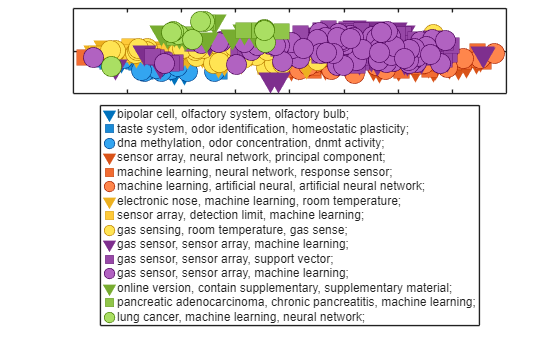

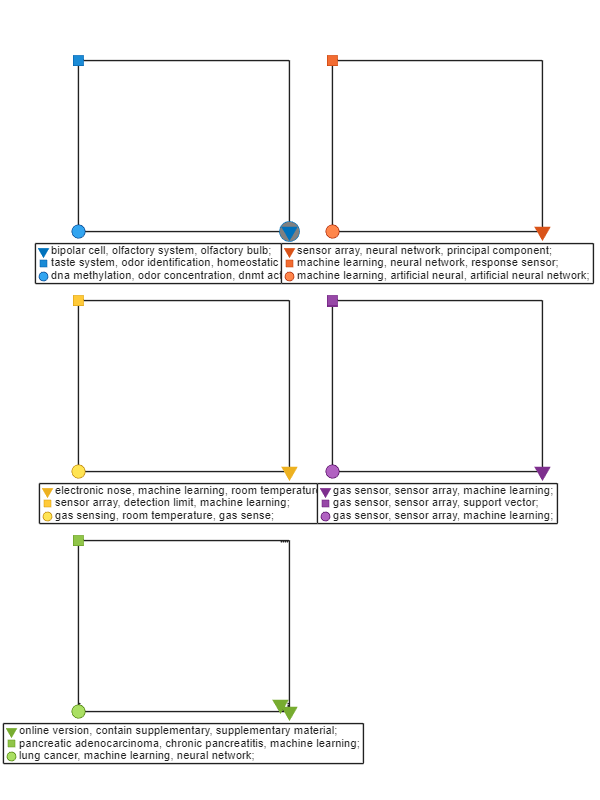

c = lines(numTopics*numClusters);
%c = colormap('hsv');
%c = c(1:floor(size(c,1)/9):end, :);
markers = ["v", "s", "o", "^"];
figure(Color=[1 1 1]), hold on, box on;
for clusterID = 1:numClusters
        xy = Y(articleClusterID == clusterID, :);
        for topicID = 1:numTopics
            tpkIdx = topTopicsCombined{clusterID} == topicID;
            plot(xy(tpkIdx,1), xy(tpkIdx,2), MarkerFaceColor=( min(c(clusterID, :) + 0.1*(topicID - 1), 1)), MarkerEdgeColor=max(c(clusterID, :) - 0.1*(topicID - 1), 0), Marker=markers(topicID), LineStyle="none", MarkerSize=15);
        end
        %plot(XY(topTopicsCombined(idx == clusterID, clusterID) == topicID,1), XY(topTopicsCombined(idx == clusterID, clusterID) == topicID,2), MarkerFaceColor=c(clusterID, :), MarkerEdgeColor=c(clusterID, :), Marker=markers(topicID), LineStyle="none");
end

% figure, hold on; grid on; box on;
% for k = 1:size(sumMiniLMEmb, 1)
%     text(Y(k, 1), Y(k, 2), string(k), FontSize=10, Color=colors(idx(k), :));
% end
legend(topWords,  Location="southoutside", NumColumns=1, AutoUpdate="off");
%plot(XY(idsSelPapers,1), XY(idsSelPapers,2),'ok', MarkerSize=10);
% for k = 1:numTopics
%     scatter(XY(topTopics == k,1), XY(topTopics == k,2), MarkerFaceColor=c(k, :), MarkerEdgeColor=c(k, :));
% end

xticklabels("");
yticklabels("");

## Split papers into clusters and save them

clear papers;
cntr = 1;
for clusterID = 1:numClusters
    selIDs = find(articleClusterID == clusterID);
    for topicID = 1:numTopics
        tpkIdx = find(topTopicsCombined{clusterID} == topicID);
        if(~isempty(tpkIdx))
            papers{cntr} = articles(selIDs(tpkIdx),["PMID", "Title", "Journal", "PubDate"]);
            writetable(papers{cntr}, "Clusters/cluster_" + (floor((cntr-1)/numTopics) + 1) +  "/topic_" + (mod(cntr - 1, numTopics)  + 1) + ".csv");
            cntr = cntr + 1;
        end
    end
end